%testing
%fs can not be modified during runtime, manually set fs in simulink!!
%Fs = 4000 %defined in simulink

Fs = 4000

%Ts = 1/Fs %defined in simulink

Ts = 2.5000e-04

Exercise = "Exercise_2C";
SampleFreq = "fs_" + 4000 + "_Hz";

Path = "HardwareMeasurements/"  ...
        + Exercise ...
        + "/" + SampleFreq 

Path = "HardwareMeasurements/Exercise_2C/fs_4000_Hz"


Path2 = "HardwareMeasurements/"  ...
        + "Exercise_2"...
        + "/" + SampleFreq 

Path2 = "HardwareMeasurements/Exercise_2/fs_4000_Hz"

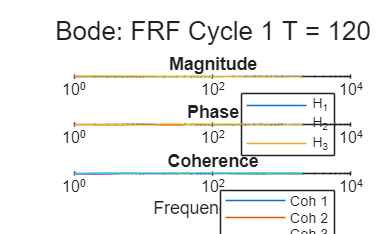

ans =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [1 1 1]
    Position: [323 225 560 337.2667]
       Units: 'pixels'

  Show all properties


PlotProcessedData([ ...
    GetProcessedData(Path,"3_point",80) ...
    GetProcessedData(Path,"3_point",16) ...
    GetProcessedData(Path2,"3_point",32)...
    %GetProcessedData(Path,"3_point",16)...
    ], ...
    "FRF Cycle 1 T = 120")

% Automated measurements per Fs
% Set the required sample frequency manually in the simulink file before running on the hardware!!
include_processing = 1 % if set to 0, only the measurements are taken and stored

include_processing = 1


% --------------------- Set before measurement ----------------------%
%Measurment Name
Exercise = "Exercise_2C";
Measurement = "Velocity_1_again_FRF_Closed_loop";
SampleFreq = "fs_" + Fs + "_Hz";

Path = "HardwareMeasurements/"  ...
        + Exercise ...
        + "/" + SampleFreq

Path = "HardwareMeasurements/Exercise_2C/fs_4000_Hz"


N_measurements = 1

N_measurements = 1

Trun = [15 30 60 120] %measurement durations

Trun =     15    30    60   120


frames = [10 30 60 120] %amount of frames

frames =     10    30    60   120



% ------------------- 2-point Controller ----------------------------%
s = tf('s');
Kp = 2;
Kd = 0.02;

f_filt = 200;
b_filt = 0.7;

C_pd = (Kp + s*Kd);
C_filter = (1)/((1/(2*pi*f_filt)^2)*s^2+((2*b_filt)/(2*pi*f_filt))*s+1);

C_total = C_pd * C_filter;

% ------------------ Calculated by program --------------------------%
samples = Trun*Fs; %measurement size per duration(samples)
nfft = zeros(length(Trun),length(frames));
for i = 1 : length(Trun)
    nfft(i,:) = Trun(i)./frames*Fs;
end
Fres = Fs./nfft;

%start running the automated measurements for n cycles
for cycles = 1 : N_measurements
    %Measuring, take 1 measurement of the longest FRF time
    [d_raw,y_raw,u_raw,e_raw,r_raw] = StartFRFMeasurement(p,samples(end),'Hardware_FRF_setup');
    
    %Store raw data
    measurementName = "Cycle" + cycles + "_" + Measurement + "_T" + Trun(end) + "_S" + samples(end);
    saveMeasurement(...
    struct("runtime", Trun(end), "fs", Fs, "samples", samples(end)), ...%settings
    struct("r", r_raw, "d",d_raw,"u",u_raw,"e",e_raw,"y",y_raw), ... %signals
    [], ...%calculatedData
    Path +'/measured_signals/'+ measurementName);
    
    for i = 1 : length(Trun)
        %Split measurement in smaller chunkes of samples
        d = d_raw(1:samples(i));
        y = y_raw(1:samples(i));
        u = u_raw(1:samples(i));
        e = e_raw(1:samples(i));
        r = r_raw(1:samples(i));
    
        %store seperated measurements
        measurementName = "Cycle" + cycles + "_" + Measurement + "_T" + Trun(i) + "_S" + samples(i);
        saveMeasurement(...
        struct("runtime", Trun(i), "fs", Fs, "samples", samples(i)), ...%settings
        struct("r", r, "d",d,"u",u,"e",e,"y",y), ... %signals
        [], ...%calculatedData
        Path +'/seperated_measured_signals/'+ measurementName);
    
        %processing
        if(include_processing ~= 0)
            for j = 1 : length(frames)
                noverlap = floor(nfft(i,j)/2);
                window = hann(nfft(i,j));
    
                % 3-point method
                [f, H, S, C] = threePoint(d,e,u,window,noverlap,nfft(i,j),Fs);
                
                %store 3-point data
                measurementName = "Cycle" + cycles + "_" + Measurement + "_T" + Trun(i) + "_Fr" + frames(j) + "_S" + samples(i) + "_nfft" + nfft(i,j);
                saveMeasurement(...
                struct("runtime", Trun(i), "fs", Fs, "samples", samples(i),"nfft", nfft(i,j),"noverlap", noverlap,"window", window, "fres", Fres(i,j)), ...%settings    
                struct("r", r, "d",d,"u",u,"e",e,"y",y), ... %signals
                struct("f",f,"H",H,"S",S,"L",[], "C",C), ...%calculatedData
                Path + '/processed_signals/3_point/'+ measurementName);
    
                % 2-point method
                [f, H, S, L, Coh, C_resp] = twoPoint(d, u, r, C_total, window, noverlap, nfft(i,j), Fs);
                
                %store 2-point data
                measurementName = "Cycle" + cycles + "_" + Measurement + "_T" + Trun(i) + "_Fr" + frames(j) + "_S" + samples(i) + "_nfft" + nfft(i,j);
                saveMeasurement(...
                struct("runtime", Trun(i), "fs", Fs, "samples", samples(i),"nfft", nfft(i,j),"noverlap", noverlap,"window", window, "fres", Fres(i,j), "C_res", C_res), ...%settings    
                struct("r", r, "d",d,"u",u,"e",e,"y",y), ... %signals
                struct("f",f,"H",H,"S",S, "L", L,"C",C), ...%calculatedData
                Path + '/processed_signals/2_point/'+ measurementName);
            end
        end
    end
end

Starting measurement with white noise on the disturbance.
If you are planning on doing an FRF measurement, 
think carefully about the signals you need and consider open/closed loop.
Starting the measurement, should take 120 seconds to collect 480000 Samples.
Measurement finished.
Retrieving measurement file(s).
Files retrieved.
